***Wireless Communications EL-GY 6023***

Homework 4 - Tommy Azzino (ta1731)

Problem 3

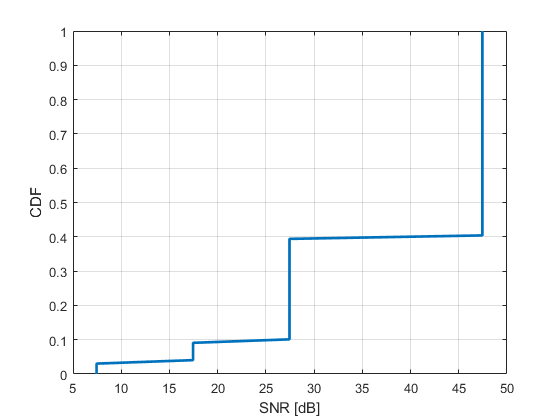

path_losses = [60, 80, 90, 100];
Ptx = 15; % dBm
B = 18e6;
N0 = -165;
N0_lin = db2pow(N0-30);
Ptx_lin = db2pow(Ptx-30);
Prx = Ptx - path_losses;
Prx_lin = db2pow(Prx-30);
SNRs_dB = pow2db(Prx_lin/(N0_lin*B));
user_distribution = [0.6, 0.3, 0.06, 0.04];
snr_cdf = [];
for i=1:length(SNRs_dB)
    snr_cdf = [snr_cdf, repelem(SNRs_dB(i), user_distribution(i)*100)];
end
figure;
plot(sort(snr_cdf), linspace(0,1,length(snr_cdf)), "LineWidth",2);
grid on;
xlabel("SNR [dB]"); ylabel("CDF");

disp(SNRs_dB(3));

   17.4473



(a)

As we can see from the plot above, we have that 95 % of the users will experience an SNR value of at least 17.4473 dB.

(c )

npoints = 10000;
snrs = linspace(-10,60,npoints);
F = zeros(npoints,1);
for i=1:npoints
    F(i) = dot((1-exp(-db2pow(snrs(i))./db2pow(SNRs_dB))), user_distribution);
end
snr_t = interp1(F,snrs,0.05);
fprintf(1, 'SNR that can be guaranteed to at least 95 perc of the users with fading [dB] = %f\n', snr_t);

SNR that can be guaranteed to at least 95 perc of the users with fading [dB] = 10.208600
